# RVC2: Chapter 3

clear all
close all
clc 


## 3.1.2 Transforming spatial velocity

这里的空间速度 与 旋量 表示的空间速度  含义 不一样

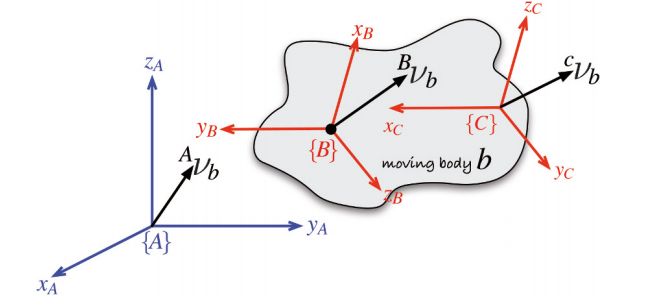

TB = SE3(1, 2, 0) * SE3.Rz(pi/2)

 

TB = 
         0        -1         0         1
         1         0         0         2
         0         0         1         0
         0         0         0         1





% body to world frame
vb = [0.2 0.3 0 0 0 0.5]';

va = TB.velxform * vb;
va'

ans =    -0.3000    0.2000         0         0         0    0.5000



% same body     与 旋量 表示的空间速度  含义 一样  ? 
TBC = SE3(0, 0.4, 0);  % T^{B}_{C}   frame {C} relative to frame {B}
TCB = inv(TBC);        % T^{C}_{B}
vc = TCB.Ad * vb;
vc'

ans =          0    0.3000         0         0         0    0.5000


## 3.1.3 Incremental rotation

rotx(0.001)

ans =     1.0000         0         0
         0    1.0000   -0.0010
         0    0.0010    1.0000


## 3.2.1 Dynamics of moving bodies

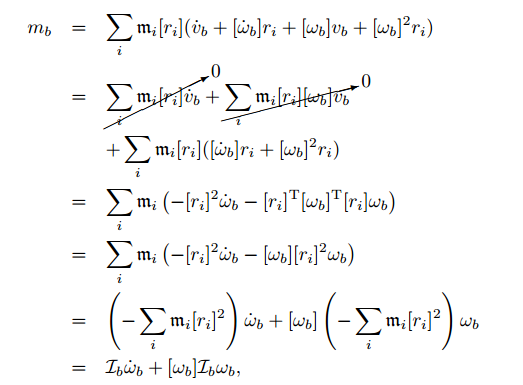

 

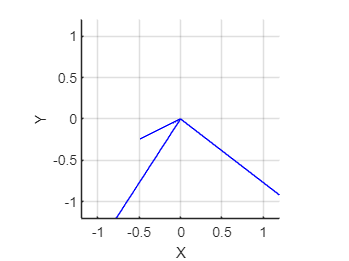

J = [2 -1 0;-1 4 0;0 0 3];  % J 是正定 对称
attitude = UnitQuaternion(); % 初始位姿

h = attitude.plot();


w = 0.2*[1 2 2]'; % 方向 [1 2 2] 和 角速度 0.2
dt = 0.05; % 步长
for t=0:dt:10
   wd =  -inv(J) * (cross(w, J*w)); % 计算角速度变化率 wd
   w = w + wd*dt;  
   attitude = attitude .* UnitQuaternion.omega(w*dt);  % 通过轴角创建的四元数
   attitude.plot('handle', h); pause(dt)
end

## 3.2.2 Transforming forces/torques

wrench example

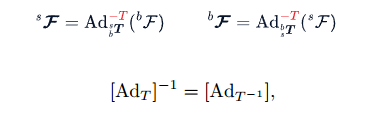


$$^{B}_{C}  T = {^{C}_{B}T}^{-1} $$


WB = [3 4 0 0 0 0]'

WB =      3
     4
     0
     0
     0
     0


WC = TBC.Ad' * WB;     %
WC'

ans =     3.0000    4.0000         0         0         0    1.2000


## 3.3 Smooth 1D trajectories

% 值 速度 加速度       初值   终值  步数/ 时间   初始速度  终速度
% [S, SD, SDD] = tpoly(S0,   SF,    M/T ,       QD0,    QD1)

tpoly(0, 1, 50);

[s,sd,sdd] = tpoly(0, 1, 50);

tpoly(0, 1, 50, 0.5, 0);


mean(sd) / max(sd)

ans = 0.5231



%                  线性段的速度
% lspb(S0, SF, M,     V)
lspb(0, 1, 50);

[s,sd,sdd] = lspb(0, 1, 50);
max(sd)

ans = 0.0306



lspb(0, 1, 50, 0.025);


lspb(0, 1, 50, 0.035);

## 3.3.2 Multi-dimensional case

clf
%  MXN                         1xN(dim)
% [Q, QD, QDD] = mtraj(TFUNC, Q0, QF, M):

q = mtraj(@lspb, [0 2], [1 -1], 50);
plot(q)


% 将位姿 T1 转为 最小参数集
% q = [T1.t' T1.torpy]  % just an example, T1 is not defined 

## 3.3.3 Multi-segment trajectoreis

机器人应用中经常要求机器人平滑地沿一条路径运动，并不停顿地经过一个或多个中间节点。

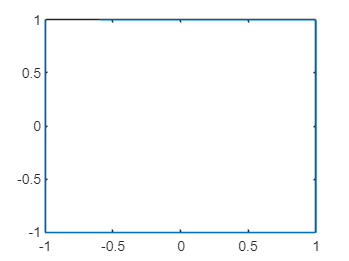

clf
% 正方形  逆时针旋转30 
% via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';

via = [-1 1; 1 1; 1 -1; -1 -1]';


%                中间点       轴速限制        初值         时间   所有段过渡的加速时间
% TRAJ = mstraj(  WP,          QDMAX, TSEG,   Q0,         DT,    TACC,  OPTIONS)
q0 = mstraj(via(:,[2 3 4 1])', [2,1],  [],   via(:,1)',  0.2,    0);


plot(q0(:,1), q0(:,2))


q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 2);
plot(q2(:,1), q2(:,2))


[numrows(q0) numrows(q2)]

ans =     30    80


## 3.3.4 Interpotation of orientation

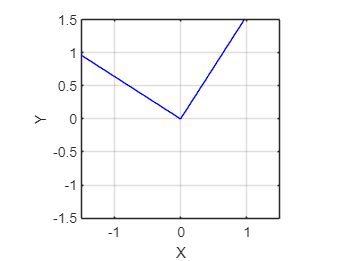

R0 = SO3.Rz(-1) * SO3.Ry(-1);
R1 = SO3.Rz(1) * SO3.Ry(1);

rpy0 = R0.torpy();   rpy1 = R1.torpy();

rpy = mtraj(@tpoly, rpy0, rpy1, 50);

SO3.rpy( rpy ).animate;


q0 = R0. UnitQuaternion;
q1 = R1.UnitQuaternion;

q = interp(q0, q1, 50);
about(q)

q [UnitQuaternion] : 1x50 (1.6 kB)


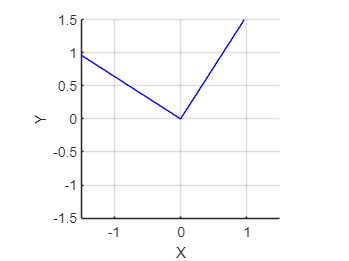

clf
q.animate()

## 3.3.5 Direction of rotation

q0 = UnitQuaternion.Rz(-2)

 
q0 = 
 
0.5403 < 0, 0, -0.84147 >
 


q1 = UnitQuaternion.Rz(2)

 
q1 = 
 
0.5403 < 0, 0, 0.84147 >
 




q11 = double(q0)

q11 =     0.5403         0         0   -0.8415


q22 = double(q1)

q22 =     0.5403         0         0    0.8415



q11 * q22'

ans = -0.4161

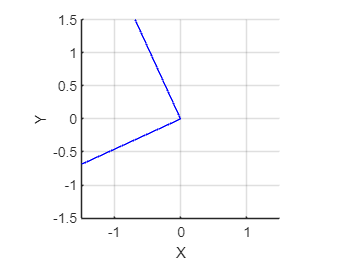

% QI = q0.interp(q1,50);
% QI.animate();
% 
% 
% QI = q0.interp(q1,50,"shortest");
% QI.animate();


q = interp(q0, q1, 50);
q.animate()


q = interp(q0, q1, 50, 'shortest');
q.animate()

## 3.3.6 Cartesian motion

T0 = SE3([0.4, 0.2, 0]) * SE3.rpy(0, 0, 3);
T1 = SE3([-0.4, -0.2, 0.3]) * SE3.rpy(-pi/4, pi/4, -pi/2);

% == T0.interp
interp(T0, T1, 0.5)

 

ans = 
    0.0975   -0.7020    0.7055         0
    0.7020    0.5510    0.4512         0
   -0.7055    0.4512    0.5465      0.15
         0         0         0         1



Ts = interp(T0, T1, 50);

about(Ts)

Ts [SE3] : 1x50 (6.4 kB)



Ts(1)

 

ans = 
   -0.9900   -0.1411         0       0.4
    0.1411   -0.9900         0       0.2
         0         0         1         0
         0         0         0         1


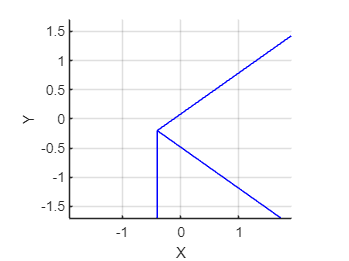


Ts.animate

%  起点 终点有速度和加速度不连续。
%   起点 终点  速度不为0  
P = Ts.transl;
plot(P)

% 起点 终点  速度不为0   加速度不为0 
rpy = Ts. torpy;
plot(rpy);



% 问题在于虽然轨迹在空间中是平滑的，但沿轨迹的步距s在时间上并不平滑。
% 所以 对步距s 进行混合插值  lspb(0,1, 50) 
Ts1 = T0. interp(T1, lspb(0,1, 50) );
P = Ts1.transl;
plot(P)


rpy = Ts1. torpy;
plot(rpy);


% ctraj 与 上面等价
Ts2 = ctraj(T0, T1, 50);
P = Ts2.transl;
plot(P)


rpy = Ts2. torpy;
plot(rpy)

## 3.4.1.2 Estimating orientation

  

这里没有用近似的表达式子 

有必要归一化，轴角 构造四元数时；  涉及到三角函数（多项式拟合），不能保证是单位四元数   

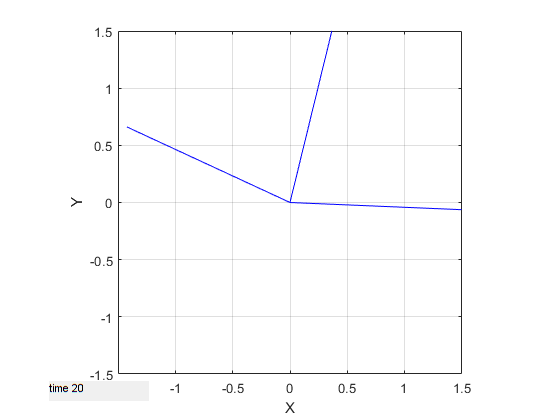

ex_tumble
attitude(1) = UnitQuaternion();
for k=1:numcols(w)-1
   attitude(k+1) = attitude(k) .* UnitQuaternion.omega( w(:,k)*dt );  % 有必要归一化
   end
attitude.animate('time', t)

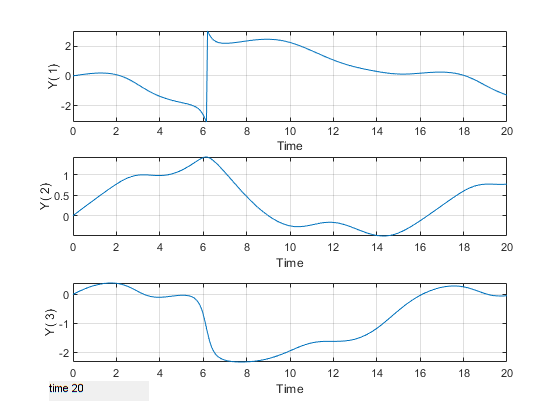

mplot(t, attitude.torpy() )

## 3.4.4 Sensor fusion

ex_tumble
attitude(1) = UnitQuaternion();
for k=1:numcols(w)-1
   attitude(k+1) = attitude(k) .* UnitQuaternion.omega( wm(:,k)*dt );
   end
clf


由于传感器信号的偏差，角误差随着时间的推移而增长

UnitQuaternion.angle 使用2.43 作为计算公式 

plot(t, angle(attitude, truth), 'r' );
hold on

**互补滤波**

[https://blog.csdn.net/u012814946/article/details/52850400](https://blog.csdn.net/u012814946/article/details/52850400)

     

  

% 显式互补滤波器
kI = 0.2; kP =1;
b = zeros(3, numcols(w));
attitude_ecf(1) = UnitQuaternion();
b = [0 0 0]';
for k=1:numcols(w)-1
   invq = inv( attitude_ecf(k) );
   % gm 加速度计测量值   mm 磁力计测量值
   sigmaR = cross(gm(:,k), invq*g0) + cross(mm(:,k), invq*m0); 
   wp = wm(:,k) - b(:,k) + kP*sigmaR;
   attitude_ecf(k+1) = attitude_ecf(k) .* UnitQuaternion.omega( wp*dt );
   b(:,k+1) = b(:,k) - kI*sigmaR*dt;
end
plot(t, angle(attitude_ecf, truth), 'b' );



###  待补充

% tr2delta ;
% delta2tr

球面线性插值 (Slerp) 与  轴角插值  是否一值 

### IMU

#### Gyroscopes  陀螺仪

#### Accelerometers 加速度计

#### Magnetometers 磁力计